## Comparison between ode23 and ode45

As the Euler method, both, `ode23 `and` ode45 `belong to the Runge-Kutta method, generally used in numeral analysis for the approximate solutions of ordinary differential equations. 

The main difference between both solvers is that `ode23` is a three-stage third-order Runge-Kutta method and `ode45` is a six-stage fifth-order Runge-Kutta method. As a result `ode45` does more work per step than `ode23.` But still, `ode 23` can take much larger steps. . 

For differential equations with smooth solutions, `ode45` is often more accurate than `ode23`. That´s why `ode45` is normally set as the default solver in MATLAB documentation and the results for the solvers may differ`.`In our case, the results of both solvers vary a little bit

## Solution with ode23

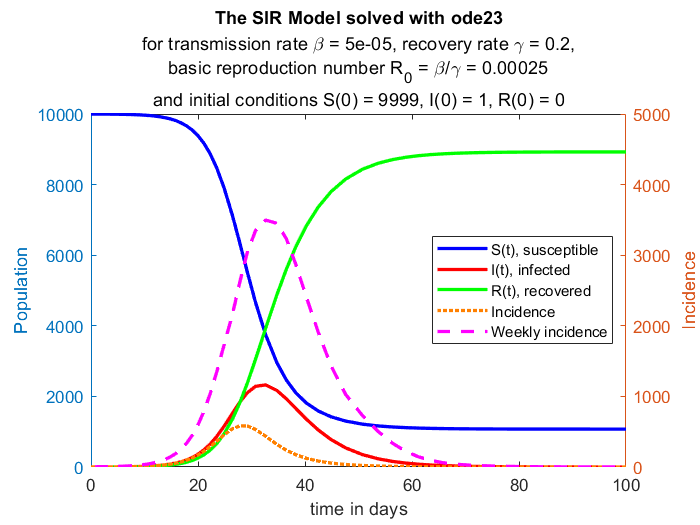

figure;

%%%% The parameters and the initial values

tRange = [0 100];
gamma = 0.2;
beta = 0.00005;
R_0=beta/gamma;
Y0 = [9999; 1; 0];

[tSol,YSol] = ode23(@SIRmodel,tRange,Y0);

%%%% The plot

S = YSol(:,1);
I = YSol(:,2);
R = YSol(:,3);

Incidence = beta*S.*I;

sz = size(tSol);
Weekly_Incidence = zeros(sz(1)-6,sz(2));

for n = 7:sz(1)

    Weekly_Incidence(n-6) = sum(Incidence(n-6:n));
 
end

yyaxis left
plot(tSol,S,'b','LineWidth',2,'LineStyle',"-"); hold on;
plot(tSol,I,'r','LineWidth',2,'LineStyle',"-");
plot(tSol,R,'g','LineWidth',2,'LineStyle',"-");
ylabel('Population');

yyaxis right
plot(tSol,Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(tSol(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylabel('Incidence');
ylim([0 5000]);

legend('S(t), susceptible', 'I(t), infected', 'R(t), recovered','Incidence', 'Weekly incidence', 'Location', 'east');
title('The SIR Model solved with ode23');
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
    ['basic reproduction number R_0 = \beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(Y0(1)),', I(0) = ',num2str(Y0(2)),', R(0) = ',num2str(Y0(3))]})

xlabel('time in days');
xlim([0 100]);

hold off;

## Solution with ode45

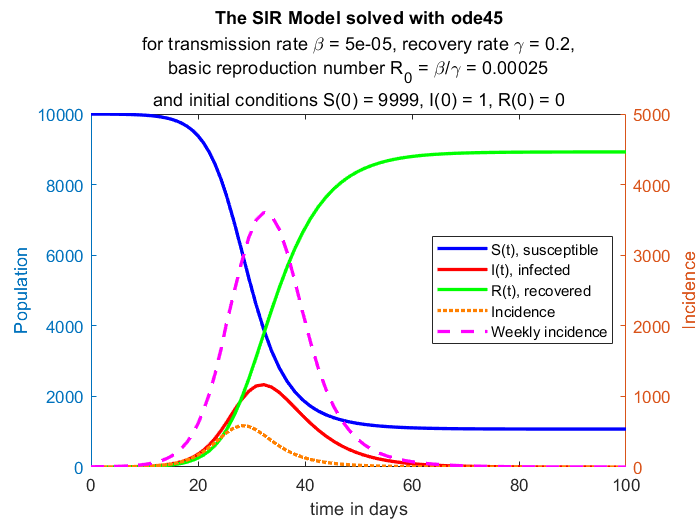

figure;

%%%% The parameters and the initial values

tRange = [0 100];
gamma = 0.2;
beta = 0.00005;
R_0=beta/gamma;
Y0 = [9999; 1; 0];

[tSol,YSol] = ode45(@SIRmodel,tRange,Y0);

%%%% The plot

S = YSol(:,1);
I = YSol(:,2);
R = YSol(:,3);

Incidence = beta*S.*I;

sz = size(tSol);
Weekly_Incidence = zeros(sz(1)-6,sz(2));

for n = 7:sz(1)

    Weekly_Incidence(n-6) = sum(Incidence(n-6:n));
 
end

yyaxis left
plot(tSol,S,'b','LineWidth',2,'LineStyle',"-"); hold on;
plot(tSol,I,'r','LineWidth',2,'LineStyle',"-");
plot(tSol,R,'g','LineWidth',2,'LineStyle',"-");
ylabel('Population');

yyaxis right
plot(tSol,Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(tSol(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylabel('Incidence');
ylim([0 5000]);

legend('S(t), susceptible', 'I(t), infected', 'R(t), recovered','Incidence', 'Weekly incidence', 'Location', 'east');
title('The SIR Model solved with ode45');
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
    ['basic reproduction number R_0 = \beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(Y0(1)),', I(0) = ',num2str(Y0(2)),', R(0) = ',num2str(Y0(3))]})

xlabel('time in days');
xlim([0 100]);

hold off;

function dYdt = SIRmodel(~,Y)

    % Extract S, I, and R from input vector Y
    S = Y(1); % susceptible
    I = Y(2); % infected
    R = Y(3); % recovered
    
    % Define the constants beta and gamma
    beta = 0.00005;
    gamma = 0.2;
    
    % Define dSdt, dIdt, dRdt from the ODEs
    dSdt = -beta*S*I;
    dIdt = beta*S*I - gamma*I;
    dRdt = gamma*I;
    
    % Create output column vector dYdt
    dYdt = [dSdt; dIdt; dRdt];
    
end